
clf
W = 5; % Width [m]
H = 3; % Depth [m]
L = 6; % Length (of extrusion) [m]

% Filament densities
rho80 = 0.8*1250;      % 100% infill [kg/m^3]
rho30 = 0.3 * 1250; %  50% infill [kg/m^3]
h = 1.75;           % Height of change of infill [m]

% Create density function
fun_rho = @(y) rho80 * (y < h) + rho30 * (y >= h);

% Generate grid of points
Npts = 200; % number of 1D spatial points (probably don't change)
xPoints = linspace(-W/2,W/2,Npts); % set of points in the x direction (horizontal)
zPoints = linspace(0,H,Npts); % set of points in the z direction (vertical)

[X, Z] = meshgrid(xPoints, zPoints); % create the meshgrid
P = [X(:)'; Z(:)'];

% Find interior points
insideBoat = transpose(P(2,:) >= H-(sqrt(2*pi)*exp(-(P(1,:).^2./2))) & P(1,:) <= H);
% Compute area elements
deltaA = (xPoints(2) - xPoints(1)) * (zPoints(2) - zPoints(1));

% Use the density function to vary the infill
masses = insideBoat .* fun_rho(P(2, :)') * deltaA * L;

% Compute the COM
CoM = (P*masses)/(dot(ones(size(masses)), masses))

CoM =     0.0000
    1.8299


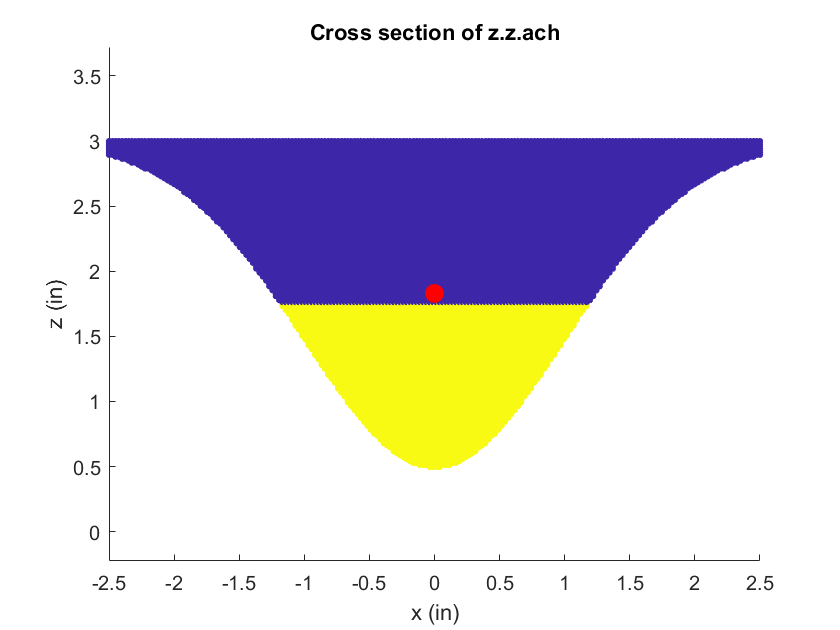


% plot only the points that are in the boat
clf


scatter(P(1,insideBoat), P(2,insideBoat), 10, masses(insideBoat), "filled"); hold on;
plot(CoM(1), CoM(2), "r.", 'MarkerSize', 32)
xlabel('x (in)');
ylabel('z (in)');
title('Cross section of z.z.ach');
axis equal

### Part 3: Compute displacement ratio

rho_water = 1000; % density of water [kg/m^3]
masses_water = insideBoat * rho_water * deltaA * L;

mass_boat = sum(masses);
mass_water = sum(masses_water);

displacement_ratio = mass_boat / mass_water

displacement_ratio = 0.5604


clf
hold on
boatcolor = [0.9290 0.6940 0.1250]; % define the color of the boat
watercolor = [0 0.4470 0.7410]; % define the color of the water
[d, moment_arm, CoB, CoM] = newtilt(P, insideBoat, rho_water, deltaA, L, fun_rho, boatdisp)

d = 2.3518

moment_arm = 9.4716e-15

CoB =     0.0000
    1.6421


CoM =     0.0000
    1.8299


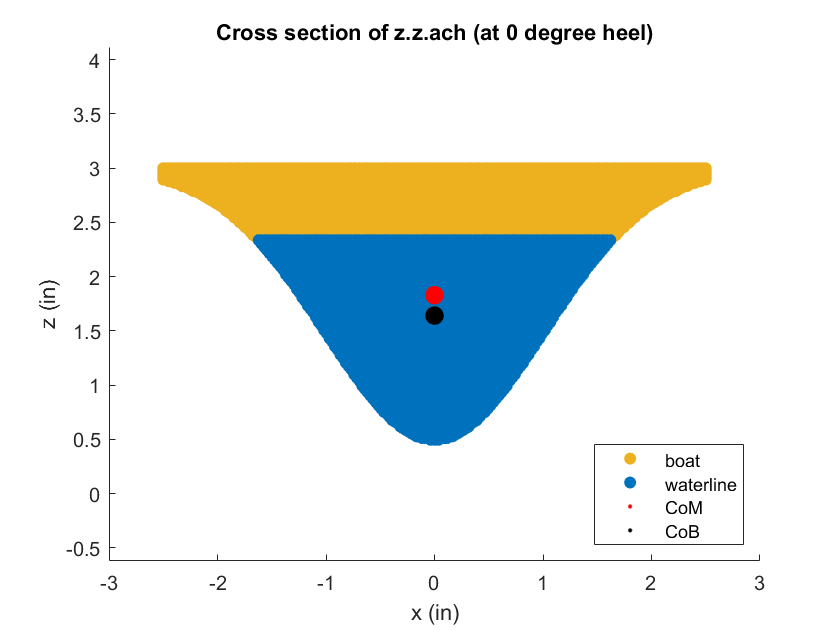

underWater = (P(2,:) <= d)'; % test if each part of the meshgrid is under the water
underWaterAndInsideBoat = insideBoat & underWater;
%scatter(P(1,insideBoat), P(2,insideBoat), 10, masses(insideBoat), "filled"); hold on;
xlabel('x (in)');
ylabel('z (in)');
title('Cross section of z.z.ach (at 0 degree heel)');
scatter(P(1,insideBoat),P(2,insideBoat),[], boatcolor,'filled') % plot the boat
scatter(P(1,underWaterAndInsideBoat),P(2,underWaterAndInsideBoat),[],watercolor, 'filled') % plot the underwater section
scatter(CoM(1,1), CoM(2,1), 1000, 'r.'); % plot the COM
scatter(CoB(1,1), CoB(2,1), 1000, 'k.'); % plot the COB
drawnow % force the graphics
set(gca, 'ylim', [0 3.5], 'xlim', [-3 3]);
legend(["boat", "waterline", "CoM", "CoB"], "Location", "southeast")
axis equal
hold off


dtheta = 10;
R = [cosd(dtheta) sind(dtheta); -sind(dtheta) cosd(dtheta)]; % define rotation matrix
P = R*P; % rotate the boat a little
[d, moment_arm, CoB, CoM] = newtilt(P, insideBoat, rho_water, deltaA, L, fun_rho, boatdisp)

d = 2.2844

moment_arm = 0.0849

CoB =     0.4394
    1.6046


CoM =     0.3544
    1.7981


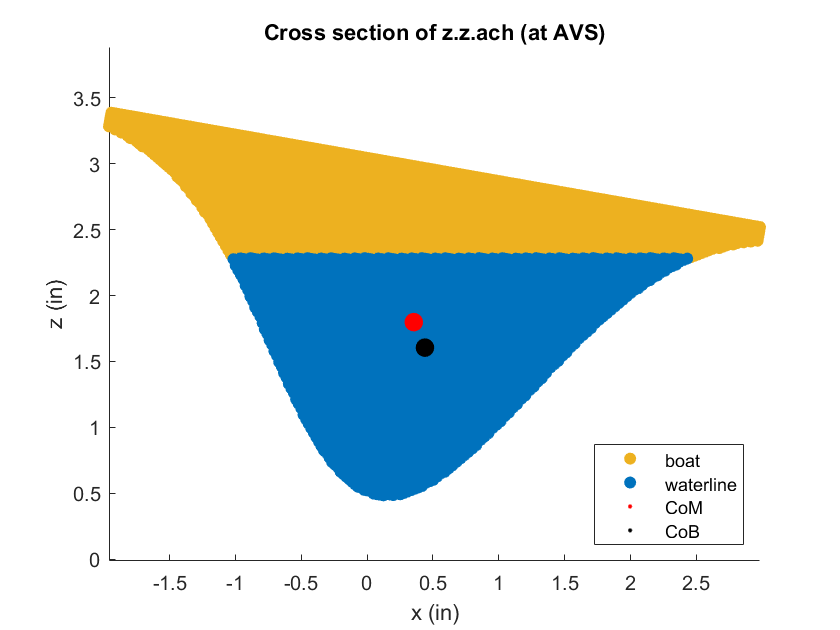

   
clf
hold on
boatcolor = [0.9290 0.6940 0.1250]; % define the color of the boat
watercolor = [0 0.4470 0.7410]; % define the color of the water
underWater = (P(2,:) <= d)'; % test if each part of the meshgrid is under the water
underWaterAndInsideBoat = insideBoat & underWater;
xlabel('x (in)');
ylabel('z (in)');
title('Cross section of z.z.ach (at AVS)');
scatter(P(1,insideBoat),P(2,insideBoat),[], boatcolor,'filled') % plot the boat
scatter(P(1,underWaterAndInsideBoat),P(2,underWaterAndInsideBoat),[],watercolor, 'filled') % plot the underwater section
scatter(CoM(1,1), CoM(2,1), 1000, 'r.'); % plot the COM
scatter(CoB(1,1), CoB(2,1), 1000, 'k.'); % plot the COB
drawnow % force the graphics
%set(gca, 'ylim', [-4 1], 'xlim', [-1 5]);
legend({"boat", "waterline", "CoM", "CoB"}, "Location", "southeast")
axis equal
hold off